# t_meshFromFreesurfer

Illustrates how to create mrVista compatible meshes from a freesurfer surface.

Dependencies: 

- Remote Data Toolbox 

- Freesurfer paths

This tutorial is part of a sequence. Run** t_initAnatomyFromFreesurfer** prior to running this tutorial. 

Summary 

- Download ernie freesurfer directory

- Create Freesurfer meshes

- Visualize with mesh viewer (external application)

- Visualize in Matlab figure

- Clean up

Tested 09/14/2016 - MATLAB r2015b, Mac OS 10.11.6

Tested 10/03/2018 - MATLAB r2017b, Mac OS 10.13.6

`See also ``t_initAnatomyFromFreesurfer`

NYU Winawer lab

## Download ernie freesurfer directory

Note that this is also done in the prior tutorial, t_initAnatomyFromFreesurfer. Doing it a second time won't hurt anyone, and it will make this tutorial work on its own, even without running the prior one in the sequence.

% Check whether freesurfer paths exist
fssubjectsdir = getenv('SUBJECTS_DIR');
if isempty(fssubjectsdir)
    error('Freesurfer paths not found. Cannot proceed.')
end

% Get ernie freesufer1 directory and install it in freesurfer subjects dir
%   If we find the directory, do not bother unzipping again
forceOverwrite = false; 

% Do it
dFolder = mrtInstallSampleData('anatomy/freesurfer', 'ernie', ...
    fssubjectsdir, forceOverwrite);

Data directory /Volumes/server/Freesurfer_subjects/ernie already exists. Skipping unzip.



fprintf('Freesurfer directory for ernie installed here:\n %s\n', dFolder)

Freesurfer directory for ernie installed here:
 /Volumes/server/Freesurfer_subjects/ernie


## Create Freesurfer meshes

% mrVista Project directory
erniePath      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');

if ~exist(erniePath, 'dir')
    % If we did not find the temporary directory created by prior
    % tutorials, then use the full directory, downloading if necessary        
    erniePath = mrtInstallSampleData('functional', 'erniePRF');
end

% Install Ernie freesurfer directory and ernie vistasession
cd(erniePath);

% Create and save meshes
hemi = 'b';
surfaces = {'white' 'pial' 'sphere' 'inflated'};
[meshes, fnames] = meshImportFreesurferSurfaces('ernie', hemi, surfaces);

FREESURFER_READ_SURF [v  1.2 ]
...reading surface file: /Volumes/server/Freesurfer_subjects/ernie/surf/lh.white
...reading triangle file
...adding 1 to face indices for matlab compatibility.
...done (  0.14 sec)

[meshSmooth]: Smoothing mesh...done. 
Coloring mesh using curvature ...done
FREESURFER_READ_SURF [v  1.2 ]
...reading surface file: /Volumes/server/Freesurfer_subjects/ernie/surf/lh.white
...reading triangle file
...adding 1 to face indices for matlab compatibility.
...done (  0.02 sec)

[meshSmooth]: Smoothing mesh...done. 
Coloring mesh using curvature ...done
FREESURFER_READ_SURF [v  1.2 ]
...reading surface file: /Volumes/server/Freesurfer_subjects/ernie/surf/lh.pial
...reading triangle file
...adding 1 to face indices for matlab compatibility.
...done (  0.09 sec)

[meshSmooth]: Smoothing mesh...done. 
Coloring mesh using curvature ...done
FREESURFER_READ_SURF [v  1.2 ]
...reading surface file: /Volumes/server/Freesurfer_subjects/ernie/surf/lh.sphere
...reading triangle f

## Visualize

% View the 4 left meshes: white, pial, inflated, sphere

for ii = 1:4
    meshVisualize(meshes(ii)) 
    % This call should open a new application, mrMeshMac or a related name
    % (depending on your OS), if it is not already open. Then it will open a
    % new window and show the mesh. You can rotate, zoom, and translate with
    % the appropriate mouse actions. We BELIEVE that the mouse buttons are as
    % follows:
    %   Rotation:  left mouse button plus movement
    %   Zoom:      right mouse button plus up/down movement
    %   Translate: left and right together plus movement

end


Loaded pnet MEX-file for the tcp/udp/ip-toolbox Compiled @ Jun  5 2014 11:14:48
Version  2.0.5  2003-09-16
Copyright (C) Peter Rydesäter, Sweden, et al. , 1998 - 2003
GNU General Public License, se license.txt for full license notis.
You are allowed to (dynamicaly) link this file with non-free code. 

   http://www.rydesater.com 


Can't establish connection to mrMeshSrv.
Can't establish connection to mrMeshSrv.
mrmInitMesh: Add mesh actor...
Adding two default lights.
Done.


ans = struct with fields:
                  name: 'Left_white'
                  type: 'vistaMesh'
                  host: 'localhost'
                    id: 1
              filename: []
                  path: []
                 actor: 32
              mmPerVox: [1 1 1]
                lights: {[1×1 struct]  [1×1 struct]}
                origin: []
          initVertices: [3×142997 double]
              vertices: [3×142997 double]
             triangles: [3×285990 double]
                colors: [4×142997 double]
             mod_depth: 0.2500
               normals: [3×142997 double]
             curvature: [1×142997 double]
            grayLayers: []
         vertexGrayMap: []
                fibers: []
    smooth_sinc_method: 0
     smooth_relaxation: 0.5000
     smooth_iterations: 32


mrmInitMesh: Add mesh actor...
Adding two default lights.
Done.


ans = struct with fields:
                  name: 'Left_pial'
                  type: 'vistaMesh'
                  host: 'localhost'
                    id: 1001
              filename: []
                  path: []
                 actor: 32
              mmPerVox: [1 1 1]
                lights: {[1×1 struct]  [1×1 struct]}
                origin: []
          initVertices: [3×142997 double]
              vertices: [3×142997 double]
             triangles: [3×285990 double]
                colors: [4×142997 double]
             mod_depth: 0.2500
               normals: [3×142997 double]
             curvature: [1×142997 double]
            grayLayers: []
         vertexGrayMap: []
                fibers: []
    smooth_sinc_method: 0
     smooth_relaxation: 0.5000
     smooth_iterations: 32


mrmInitMesh: Add mesh actor...
Adding two default lights.
Done.


ans = struct with fields:
                  name: 'Left_sphere'
                  type: 'vistaMesh'
                  host: 'localhost'
                    id: 1003
              filename: []
                  path: []
                 actor: 32
              mmPerVox: [1 1 1]
                lights: {[1×1 struct]  [1×1 struct]}
                origin: []
          initVertices: [3×142997 double]
              vertices: [3×142997 double]
             triangles: [3×285990 double]
                colors: [4×142997 double]
             mod_depth: 0.2500
               normals: [3×142997 double]
             curvature: [1×142997 double]
            grayLayers: []
         vertexGrayMap: []
                fibers: []
    smooth_sinc_method: 0
     smooth_relaxation: 0.5000
     smooth_iterations: 32


mrmInitMesh: Add mesh actor...
Adding two default lights.
Done.


ans = struct with fields:
                  name: 'Left_inflated'
                  type: 'vistaMesh'
                  host: 'localhost'
                    id: 1005
              filename: []
                  path: []
                 actor: 32
              mmPerVox: [1 1 1]
                lights: {[1×1 struct]  [1×1 struct]}
                origin: []
          initVertices: [3×142997 double]
              vertices: [3×142997 double]
             triangles: [3×285990 double]
                colors: [4×142997 double]
             mod_depth: 0.2500
               normals: [3×142997 double]
             curvature: [1×142997 double]
            grayLayers: []
         vertexGrayMap: []
                fibers: []
    smooth_sinc_method: 0
     smooth_relaxation: 0.5000
     smooth_iterations: 32


## Alernative visualiztion in Matlab

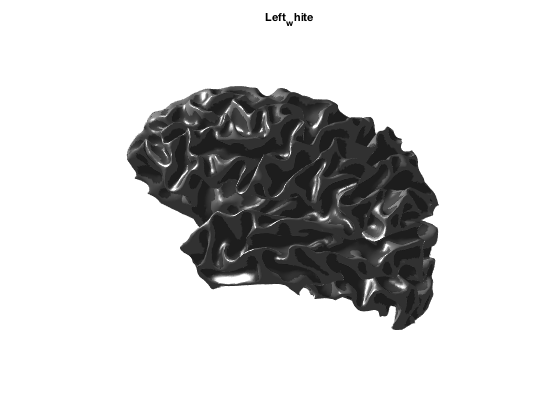

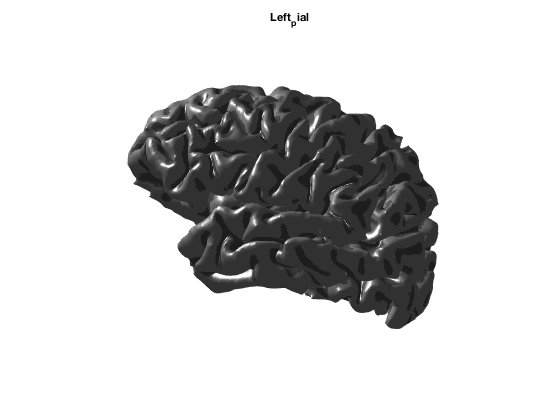

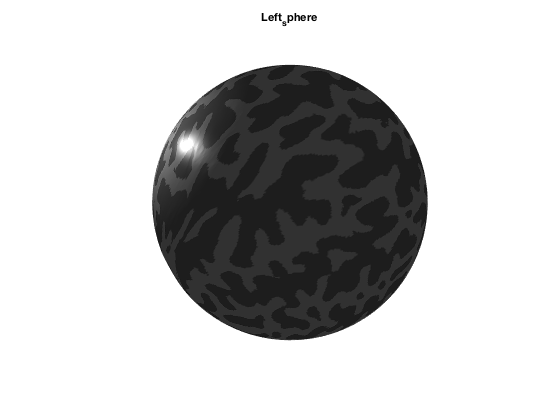

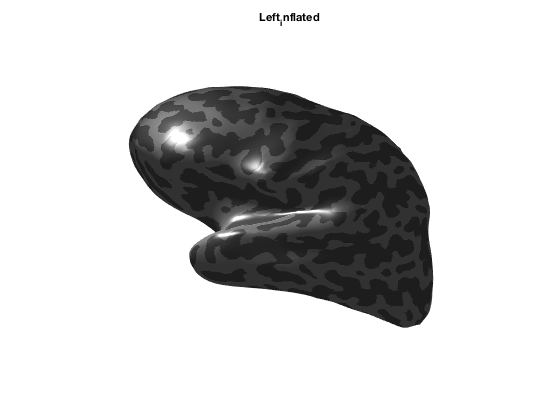

for m = 1:4
    
    figure,
    
    % Faces (also called triangles) are defined by 3 points, each of
    % which is an index into the x, y, z vertices
    faces = meshes(m).triangles' + 1; % we need to 1-index rather than 0-index for Matlab
    
    % The vertices are the locations in mm spacing
    x     = meshes(m).vertices(1,:)';
    y     = meshes(m).vertices(2,:)';
    z     = meshes(m).vertices(3,:)';
    
    % The colormap will, by default, paint sulci dark and gyri light
    c     = meshes(m).colors(1,:)';
    
    % Render the triangle mesh
    tH = trimesh(faces, x,y,z);
    
    % Make it look nice
    set(tH, 'LineStyle', 'none', 'FaceColor', 'interp', 'FaceVertexCData',c)
    axis equal off; colormap gray; set(gca, 'CLim', [0 255])
    
    % Lighting to make it look glossy
    light('Position',100*[0 1 1],'Style','local')
    lighting gouraud
    
    % Which mesh are we plotting?
    title(meshes(m).name)
    
    % Rotate it
    set(gca, 'View', [-16.7000  -90.0000]);
    
end